clc
clear all
close all

robot_name = '5R';
model = 'bilinear';
modality = '3D';
robot_path = strcat('saved_models/',robot_name,'/',model,'/',modality,'/matlab_files/');
addpath(robot_path)
addpath("paths/")
addpath("models/")
addpath("dynamics/robot_models/")

robot = robot_selector(robot_name, modality)

robot =   rigidBodyTree with properties:

     NumBodies: 6
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'link_1'  'link_2'  'link_3'  'link_4'  'link_5'  'link_ee'}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'column'


% load neural maps
forward_map_data = load("forward_map.mat")

forward_map_data = struct with fields:
        map_in_weights: [20×5 single]
           map_in_bias: [0.0319 -2.8052e-04 -0.0125 -0.1398 0.0058 -4.4107e-04 0.3583 0.3981 0.0082 -0.0516 -1.8592 0.1169 -0.0046 -0.0039 0.0029 -1.6694 -1.7259 0.0052 -0.0092 0.3992]
      map_hidden_depth: 3
    map_hidden_weights: [20×20×3 double]
       map_hidden_bias: [1×20×3 double]
       map_out_weights: [3×20 single]
          map_out_bias: [-0.3997 0.0272 0.0074]


encoder_data = load("encoder.mat")

encoder_data = struct with fields:
        encoder_in_weights: [30×10 single]
           encoder_in_bias: [-0.3075 0.0786 -0.7421 0.7548 -0.1564 0.6099 0.2607 -0.2710 -1.0636 -8.1469e-04 0.3993 0.0373 -0.2477 0.0753 0.0107 0.2970 -1.1206 -0.3465 -0.7085 0.4599 -0.7317 0.0664 -0.6432 -4.3653e-04 0.9409 0.3179 -0.4945 0.4253 … ]
      encoder_hidden_depth: 2
    encoder_hidden_weights: [30×30×2 double]
       encoder_hidden_bias: [1×30×2 double]
       encoder_out_weights: [38×30 single]
          encoder_out_bias: [0.1766 0.0880 -0.1628 0.0545 0.1389 -0.1941 0.0088 0.2146 0.1350 -0.3200 -0.0911 0.2373 -0.0967 -0.1234 -0.2536 0.2070 0.0489 0.0942 0.0812 0.0544 0.1893 0.0562 -0.0677 -0.0712 0.2056 -0.2298 -0.1114 0.2788 0.0800 0.0836 … ]



load("dyn_mat.mat")
load("std.mat")

%discrete time parameters
Ad = A;
Bd = B;

%continuous time parameters
delT = 0.005;
N = size(A,1); %lifted dimension
m= length(robot.gravityTorque); %number of controls
Ac = (A-eye(N))/delT;
Bc = B/delT;
Cc = C;
Cc_red = C(1:m,:);

%ZNN IMPLEMENTATION
shape = "lissajous"

shape = "lissajous"

if strcmp(modality, '3D')
    num_states_cart = 3;
elseif strcmp(modality, '2D')
    num_states_cart = 2;
end
% Parameters 
% 3R 2D %0.012 cardiod % 0.01 hypercycloid % 0.01 epicycliod
% 4R 3D %0.012 cardiod % 0.1 epicycloid
% 5R 3D %0.012 cardiod % 0.012 lissajous

c = 0.012; %0.012 cardiod % 0.1 3R
tilt = pi/6;
T = 10;
n=1;
iterations = T/delT;
t_span = 0:delT:T;
lambda= diag([10,10, 10, 100, 100, 100]) ;%
% 3R 2D %diag([100,100,300,300]) cardiod % diag([10,10,00,100]) hypocycloid % diag([10,10,00,100]) epicycloid
% 4R 3D %0.012 cardiod % 0.1 epicycloid
% 5R 3D %diag([10,10, 10, 100, 100, 100] cardiod % diag([10,10, 10, 100, 100, 100] lissajous 

% diag([10,10,10,100,100,100]); % cardiod 1

u_plus_og = 0.3*ones(m,1);
if standardize == 1
    u_plus = (u_plus_og - mean')./scale';
end
u_minus = -u_plus;
phi = diag(u_plus-u_minus);
u(:,1) = 0*ones(m,1);

chi(:,1) = log((u(:,1)-u_minus)./(u_plus-u(:,1)));

tic

%inverse map for cardioid pat
if strcmp(robot_name,'3R')
    theta_traced(:,1) = [pi/4;pi/4;-pi/4];%[-1.32444859; -0.74052581; 1.1733985];%[pi/4;pi/4;-pi/4];
elseif strcmp(robot_name,'4R')
    theta_traced(:,1) = 3*[pi/4;pi/4;-pi/4; pi/4];
elseif strcmp(robot_name,'5R')
    theta_traced(:,1) = [pi/4;pi/4;-pi/4; -pi/4; pi/4];  
end

hom_tf = getTransform(robot,theta_traced(:,1),'link_ee');
if strcmp(modality,'2D')
    x_actual_traced(:,1) = hom_tf(1:num_states_cart,4);
    [x_desired(:,1),xd_dot(:,1),xd_ddot(:,1)] = path_2D(c,tilt, x_actual_traced(:,1),0, T, shape);
    
       
else
    x_actual_traced(:,1) = hom_tf(1:num_states_cart,4);
    [x_desired(:,1),xd_dot(:,1),xd_ddot(:,1)] = path_3D(c,tilt, x_actual_traced(:,1),0, T, shape);
    
end
x_traced(:,1) = x_actual_traced(:,1);
x_traced_dot(:,1) = xd_dot(:,1);
theta_desired(:,1) = theta_traced(:,1);

W = neural_jacobian(theta_traced(:,1), forward_map_data);
theta_dot_desired(:,1) = pinv(W)*xd_dot(:,1);
theta_dot_traced(:,1) = theta_dot_desired(:,1);

%lifting
states_traced(:,1) = [theta_traced(:,1);   % states consists of theta and theta_dot
                      theta_dot_traced(:,1)];

z = lifting(states_traced(:,1),encoder_data);
z_dot(:,1) = Ac*z(:,1)+Bc*kron(u(:,1),z(:,1));

for i=1:iterations
    t = t_span(i);
    if strcmp(modality,'2D')
        [x_desired(:,i), xd_dot(:,i),xd_ddot(:,i)] = path_2D(c,tilt, x_actual_traced(:,1),t, T, shape);
    else
        [x_desired(:,i), xd_dot(:,i),xd_ddot(:,i)] = path_3D(c,tilt, x_actual_traced(:,1),t, T, shape);
    end
     
    error(:,i) = [x_traced(:,i); x_traced_dot(:,i)] - [x_desired(:,i); xd_dot(:,i)];

    %Jacobian parameters
    W = neural_jacobian(theta_traced(:,i),forward_map_data);
    W_dot = neural_jacobian_dot(theta_traced(:,i),theta_dot_traced(:,i),forward_map_data);
    
    J_tilde = [W zeros(size(W));
                W_dot W];

    psi = diag(exp(chi(:,i))./(1+exp(chi(:,i))).^2);

    
    z_dot(:,i)=Ac*z(:,i)+Bc*kron(u(:,i),z(:,i));

    chi_dot = pinv(Bd*kron(eye(m),z(:,i))*phi*psi)*(-Ad*z_dot(:,i) - Bd*kron(u(:,i),z_dot(:,i))  + pinv(J_tilde*Cc)*([xd_dot(:,i);xd_ddot(:,i)] - lambda*error(:,i)));


    if i<=3
        chi(:,i+1) = chi(:,i)+chi_dot*delT;
    % elseif i>2 && i<=3
    %     chi(:,i+1) = (2*delT*chi_dot+4*chi(:,i)-chi(:,i-1))/3;
    % elseif i>3
    %     chi(:,i+1) = (12*delT*chi_dot+36*chi(:,i)-4*chi(:,i-2))/32;
    % 
    %  end

    else %FIFD
        chi(:,i+1) = (8/5)*chi_dot*delT + (3/5)*chi(:,i) + (1/5)*chi(:,i-1)+ (1/5)*chi(:,i-2); %FIFD
    end

    u(:,i+1) = phi*(exp(chi(:,i+1))./(1+exp(chi(:,i+1))))+u_minus;
    
    if standardize == 1
        u(:,i) = (u(:,i).*scale') + mean';
    end

     th_ddot = forwardDynamics(robot,theta_traced(:,i),theta_dot_traced(:,i),u(:,i));

    if i<=3
        theta_dot_traced(:,i+1) = theta_dot_traced(:,i) + th_ddot*delT;
        theta_traced(:,i+1) = theta_traced(:,i) + theta_dot_traced(:,i+1)*delT;
    else %FIFD
        theta_dot_traced(:,i+1) = (8/5)*th_ddot*delT + (3/5)*theta_dot_traced(:,i) ...
                                 + (1/5)*theta_dot_traced(:,i-1)+ (1/5)*theta_dot_traced(:,i-2); %FIFD
        theta_traced(:,i+1) = (8/5)*theta_dot_traced(:,i)*delT + (3/5)*theta_traced(:,i) ...
                            + (1/5)*theta_traced(:,i-1)+ (1/5)*theta_traced(:,i-2); %FIFD
    end
     % [theta_traced(:,i+1), theta_dot_traced(:,i+1)] = dynamics_3R(u(:,i),theta_traced(:,i),theta_dot_traced(:,i));
     states_traced(:,i+1) = [theta_traced(:,i+1);theta_dot_traced(:,i+1)];
     z(:,i+1) = lifting(states_traced(:,i+1),encoder_data);
     
     x_traced(:,i+1) = neural_forward_map(theta_traced(:,i+1),forward_map_data);
     x_traced_dot(:,i+1) = neural_jacobian(theta_traced(:,i+1),forward_map_data)*theta_dot_traced(:,i+1);
     hom_tf = getTransform(robot,theta_traced(:,i+1),'link_ee');
     x_actual_traced(:,i+1) = hom_tf(1:num_states_cart,4);
   
     % x_actual_traced(:,i+1) = forward_map_3R_real(theta_traced(:,i+1));
end

% end_time = tic;
% time_taken = end_time-start_time
toc

Elapsed time is 5.108895 seconds.


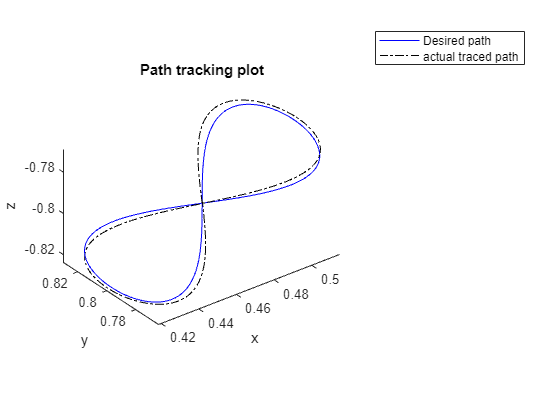

figure()
if strcmp(modality, '3D')
    % plot3(x_traced(1,:),x_traced(2,:),x_traced(3,:))
    % hold on
    plot3(x_desired(1,:),x_desired(2,:),x_desired(3,:),"b")
    hold on
    plot3(x_actual_traced(1,:), x_actual_traced(2,:),x_actual_traced(3,:),"k-.")
    xlabel("x")
    ylabel("y")
    zlabel("z")
    title("Path tracking plot")
    legend("Desired path", "actual traced path")
    axis("equal")
    hold off
elseif strcmp(modality, '2D')
    % plot(x_traced(1,:),x_traced(2,:))
    % hold on
    plot(x_desired(1,:),x_desired(2,:),"b")
    hold on
    plot(x_actual_traced(1,:), x_actual_traced(2,:),"k-.")
    xlabel("x")
    ylabel("y")
    title("Path tracking plot")
    legend("Desired path", "actual traced path")
    axis("equal")
    hold off
    

end

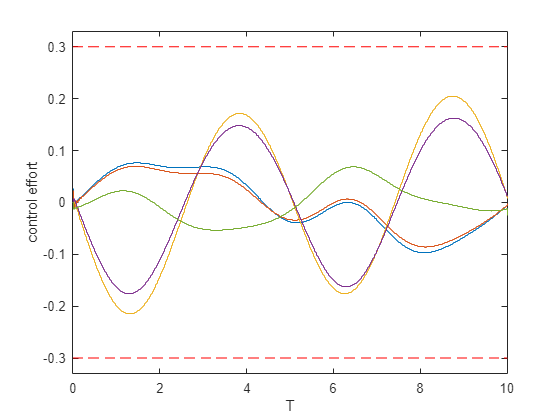

%plots
%control effort plot
figure()
for i = 1:m
 stairs(t_span(1:end),u(i,:))
 hold on
end
plot([0,T],[u_plus_og(1),u_plus_og(1)], 'r--' ,[0,T],[-u_plus_og(1),-u_plus_og(1)],'r--')
hold on
xlabel("T")
ylabel('control effort')
ylim([-1.1*u_plus_og(1)  1.1*u_plus_og(1)])
hold off

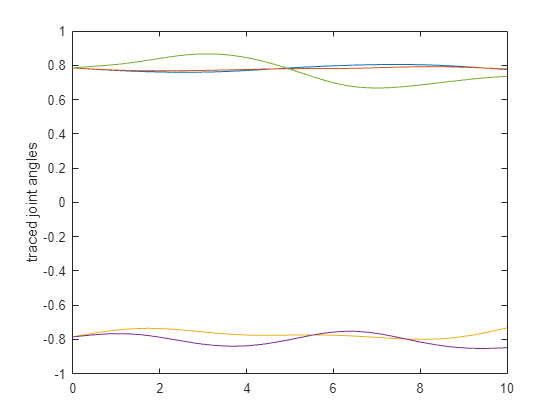

%states traced plot
figure()
for i  = 1:m
    plot(t_span,states_traced(i,:))
    hold on
end

ylabel('traced joint angles')
hold off

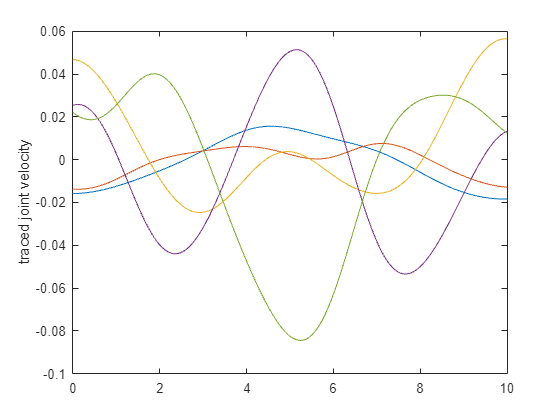

figure()
for i  = 1:m
    plot(t_span,states_traced(m+i,:))
    hold on
end

ylabel('traced joint velocity')
hold off

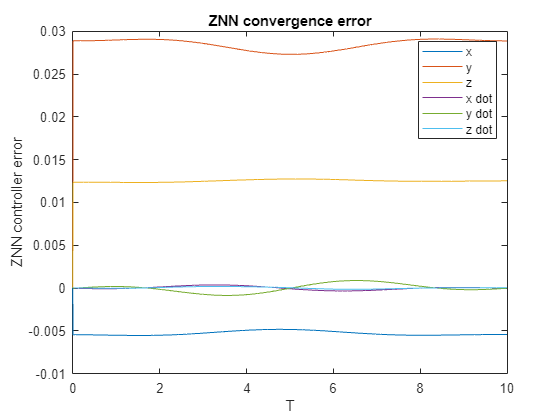

figure()
%error plot
plot(t_span(1:end-1),error)
xlabel('T')
ylabel("ZNN controller error")
if strcmp(modality, '2D') == 1
    legend("x","y","x dot","y dot")
else
    legend("x","y", "z","x dot","y dot", "z dot")
end
title("ZNN convergence error")

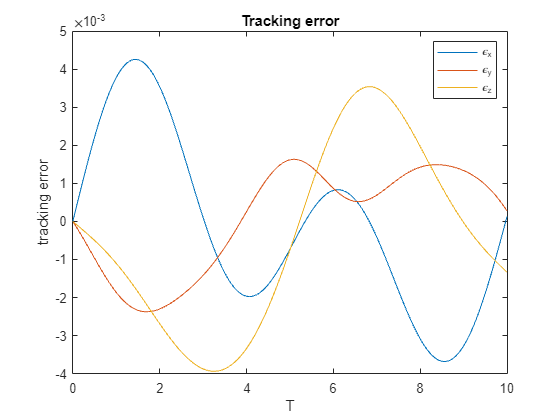

figure()
%error plot
tracking_error = x_desired-x_actual_traced(:,1:end-1);
plot(t_span(1:end-1),tracking_error)
xlabel('T')
ylabel("tracking error")
title("Tracking error")

if strcmp(modality, '2D') == 1
    legend("\epsilon_x","\epsilon_y")
else
    legend("\epsilon_x","\epsilon_y","\epsilon_z")
end
hold off

%control effort required
u_norm = sum(vecnorm(u)*delT)

u_norm = 1.8344

%tracking error norm
tracking_error_norm = sum(vecnorm(x_desired-x_actual_traced(:,1:end-1))*delT)/T

tracking_error_norm = 0.0034

%tracking error norm
controller_error_norm = sum(vecnorm(error)*delT)/T

controller_error_norm = 0.0315